# LQT環境の作成

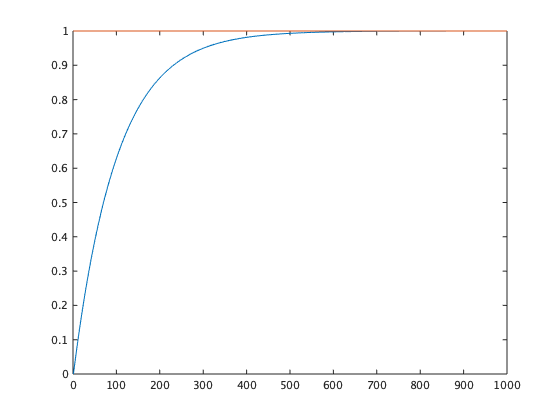

T = 1;
K = 1;
[A, B, C, D] = tf2ss([K], [T 1]);
sys = ss(A,B,C,D);
sysd = c2d(sys, 0.01);

env = DiscreteLQTEnv(sysd.A, sysd.B, sysd.C, 1, 1, 1, [0;1]);

state = env.reset();
x(1, :) = state;

for i = 2 : 1000
    [state, ~, ~ ,~] = env.step(1);
    x(i, :) = state;
end

plot(x);